# Cargar información de NDVI RCAT

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*

%clearvars -except area_estudio;
clear;
close all;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok



%directorio de datos
dir_data = "D:\DATA\";

% % %Ventana para el mapa region hidrografica rio panuco
% lon_mapa = [-98.7 -96.8];
% lat_mapa = [19.8 21.9];

% lon_mapa = [-99.5 -95.2];
% lat_mapa = [17.8 22.5];

lon_mapa = [-98.8 -96.8];
lat_mapa = [19.9 21.8];

% % 
% % %cuadrante de inicio y tamaño del area de estudio
coord_1k_v6_inicio = [3950 3950];
coord_1k_v6_tam = [455 850];
% % 
%h08v06
coord_1k_v7_inicio = [3950 0];
coord_1k_v7_tam = [455 30];
% % 
 ndvi_tam = [455 880];


## Obtener matrices de latitud longitud

info_hdf = f_infohdfs2table(dir_data,"MOD13Q1");

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 46 archivos



[num_registros,~] = size(info_hdf);

if (num_registros > 0)
    [lat,lon,ndvi]=f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## **Crear el área de estudio**

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area","var");
if ae == 0
    ae = exist("study_area.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load study_area;
    else
        disp("Creando area de estudio");
        study_area = f_create_study_area(dir_data+'KML\Area_study.kml',lat,lon);
        save ("study_area.mat",'study_area');
    end
else
    if( numel(study_area) <= 1)
        disp("La variable area_estudio sera sustituida");
        study_area = f_create_study_area(dir_data+'KML\Area_study.kml',lat,lon);
        save ("study_area.mat",'study_area');
    else
        disp(">>> Área de estudio existente");
    end
end

>>> Cargando área de estudio



ndvi = double(ndvi) .* 0.0001;
ndvi(study_area==false)=nan;

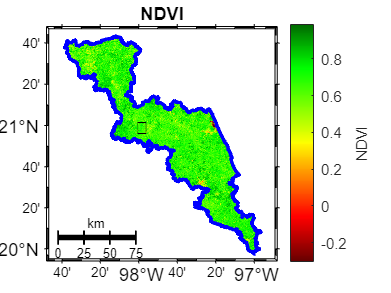


f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI",[],"NDVI","NDVI");
f_draw_kml(dir_data,"Area_study",2,'b',0);


%%promedio_ndvi = mean(ndvi,"all");


## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
tmp = find(  info_hdf.anio == 2022 );
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_re = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(study_area==false)=NaN;
    disponibilidad(study_area==false)=NaN;

     %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_re(:,:,i) = disponibilidad;
 
    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


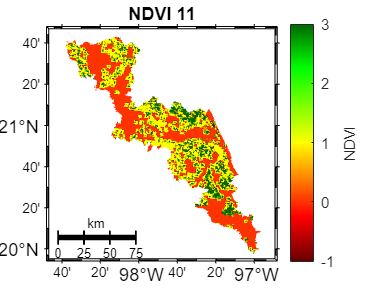


% for i=1:num_registros
   % Mostrar algun registro
idx=11;

%     f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,idx),"NDVI "+idx,[],"NDVI","NDVI");
    f_draw_map(lon_mapa,lat_mapa,lon,lat,arr_ndvi_re(:,:,idx),"NDVI "+idx,[],"NDVI","NDVI");

% end

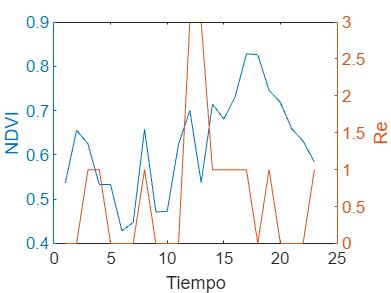


serie = reshape(arr_ndvi(300,400,:),[],1);
serie_re = reshape(arr_ndvi_re(320,400,:),[],1);

figure;
yyaxis left 
plot(serie);
xlabel('Tiempo')
ylabel('NDVI')
yyaxis right
plot(serie_re);
ylabel('Re')